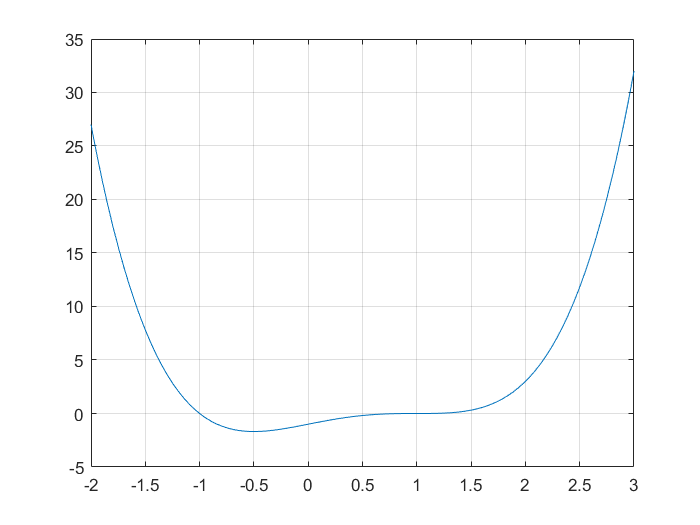

%%5
syms n x;
P = sym2poly(subs(x^(2*n)-n*x^(n+1)+n*x^(n-1)-1,n,2));
r = roots(P);
x = linspace(-2, 3, 100);
f = polyval(P,x);
plot(x,f);
grid on;
hold on;

%%9
n = 3;
M = randi([-100,100],n,n)

M =     93    92   -72
   -69    -3   -16
    95    60    84


[R,D] = eig(M);
P1 = poly(D);
P2 = poly(M);
if P1 == P2
    disp("Yes");
else
    disp("No");
end

Yes
